%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors      :-  Manas Kumar Mishra, Niranjana Vannadil 
% Project name :-  SEA (Statistical Enhancement of Audio)
% Organization :-  IIITDM Kancheepuram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Noisy clips
% 1. TempleNoisyclip1_Agra.mp3
% 2. TempleNoisyclip2_Agra.mp3
% 3. TempleNoisyclip1_Agra.wav
% 4. TempleNoisyclip2_Agra.wav
% 5. TestAudio4.wav

[samples, fsample] = audioread('TestSongs/TestAudio4.wav');

% player = audioplayer(samples, fsample);
% play(player);

fsample %sampling frequency of audio 

fsample = 44100

samples %Samples, right and left channel

samples =    -0.0131   -0.0108
   -0.0084   -0.0041
   -0.0028    0.0061
    0.0026    0.0156
    0.0060    0.0209
    0.0064    0.0199
    0.0049    0.0141
    0.0027    0.0070
    0.0017    0.0020
    0.0025    0.0014


% PSD Show

ShowPSD(samples, fsample);



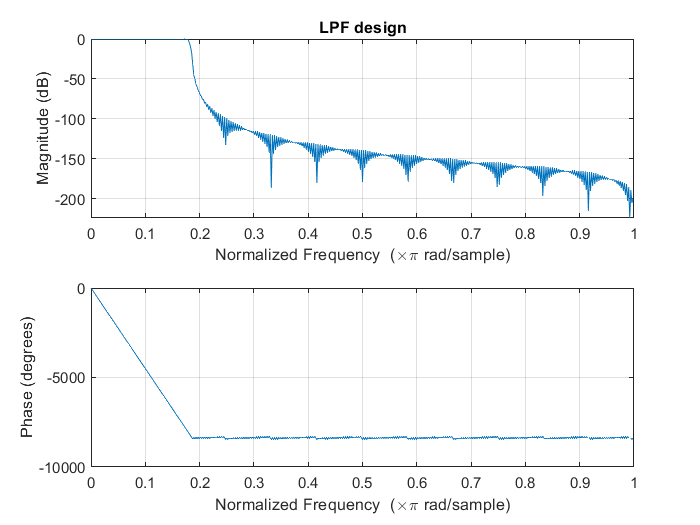

% Preprocessing step
Cutoff = 0.182;

filterLength =500;

filterCoff = impulseResponseOfFilterLPF(Cutoff, filterLength, 3);

NewSamples1 = myFIRFilter(samples(:, 1)', filterCoff);
NewSamples2 = myFIRFilter(samples(:, 2)', filterCoff);
NewSample = [NewSamples1', NewSamples2'];




% player = audioplayer(NewSample, fsample);
% play(player);


% PSD view
ShowPSD(NewSample, fsample);


% Output = MMSESTSA84(NewSample, fsample);

% player = audioplayer(Output, fsample);
% play(player);


a= rand(1, 44100)

a =     0.6648    0.0218    0.3042    0.1237    0.5880    0.6135    0.7908    0.7116    0.9415    0.4820    0.5445    0.4696    0.6877    0.1673    0.2902    0.5660    0.4006    0.1112    0.8491    0.4776    0.3835    0.2177    0.5753    0.4705    0.5057    0.5075    0.3235    0.1122    0.3144    0.0659    0.1386    0.2540    0.1460    0.8845    0.1141    0.9322    0.8407    0.4622    0.1920    0.2522    0.8205    0.4203    0.2941    0.8826    0.8690    0.8178    0.0429    0.6837    0.8350    0.2619



W= ceil(0.032*44100)

W = 1412

Window = hamming(W);
overlappPerc=0.75;
sp = 1-overlappPerc

sp = 0.2500


Window=Window(:);
% a1= NewSample(:, 1)';
L=length(a);

SP=fix(W.*sp);

N=fix((L-W)/SP +1); %number of segments

repmat(1:W, N, 1);
repmat((0:(N-1))'*SP,1,W);
Index=(repmat(1:W,N,1)+repmat((0:(N-1))'*SP,1,W))'

Index =            1         354         707        1060        1413        1766        2119        2472        2825        3178        3531        3884        4237        4590        4943        5296        5649        6002        6355        6708        7061        7414        7767        8120        8473        8826        9179        9532        9885       10238       10591       10944       11297       11650       12003       12356       12709       13062       13415       13768       14121       14474       14827       15180       15533       15886       16239       16592       16945       17298
           2         355         708        1061        1414        1767        2120        2473        2826        3179        3532        3885        4238        4591        4944        5297        5650        6003        6356        6709        7062        7415        7768        8121        8474        8827        9180        9533        9886       10239       10592       10945       

hw=repmat(Window,1,N);
Seg=a(Index);
Seg=a(Index).*hw;

Seg

Seg =     0.0532    0.0331    0.0741    0.0068    0.0088    0.0536    0.0412    0.0790    0.0790    0.0793    0.0329    0.0768    0.0196    0.0679    0.0349    0.0798    0.0201    0.0102    0.0330    0.0750    0.0100    0.0016    0.0242    0.0068    0.0428    0.0432    0.0262    0.0482    0.0038    0.0380    0.0040    0.0232    0.0035    0.0469    0.0759    0.0588    0.0359    0.0368    0.0089    0.0662    0.0278    0.0462    0.0311    0.0088    0.0546    0.0401    0.0160    0.0572    0.0162    0.0053
    0.0017    0.0190    0.0512    0.0163    0.0613    0.0112    0.0405    0.0142    0.0345    0.0131    0.0183    0.0343    0.0074    0.0652    0.0358    0.0391    0.0200    0.0654    0.0595    0.0717    0.0714    0.0097    0.0653    0.0198    0.0663    0.0419    0.0124    0.0682    0.0017    0.0216    0.0640    0.0704    0.0315    0.0090    0.0305    0.0470    0.0417    0.0306    0.0256    0.0278    0.0545    0.0230    0.0766    0.0440    0.0779    0.0484    0.0179    0.0569    0.0718   

% Framing of the sample values
conSampleLength = 0.032

conSampleLength = 0.0320

WinLen = ceil(conSampleLength*fsample);
overlappPerc = 0.75;

[frame1, frame2]= Framing(NewSample,WinLen, overlappPerc, 1);
[FrameSize, NumOfFrame]=size(frame1)

FrameSize = 1412

NumOfFrame = 5980


% Fourier transform of the framed part
FSAMPLE1 = fft(frame1);

FSAMPLE1 = 	1.0e+02 *

   0.0067 + 0.0000i   0.0136 + 0.0000i   0.0072 + 0.0000i  -0.0269 + 0.0000i  -0.0441 + 0.0000i  -0.0107 + 0.0000i   0.0273 + 0.0000i   0.0232 + 0.0000i   0.0070 + 0.0000i   0.0046 + 0.0000i  -0.0012 + 0.0000i  -0.0042 + 0.0000i  -0.0062 + 0.0000i  -0.0025 + 0.0000i   0.0036 + 0.0000i  -0.0036 + 0.0000i  -0.0117 + 0.0000i  -0.0060 + 0.0000i   0.0005 + 0.0000i  -0.0064 + 0.0000i  -0.0062 + 0.0000i   0.0130 + 0.0000i   0.0178 + 0.0000i  -0.0028 + 0.0000i  -0.0171 + 0.0000i  -0.0152 + 0.0000i  -0.0031 + 0.0000i   0.0117 + 0.0000i   0.0066 + 0.0000i  -0.0122 + 0.0000i  -0.0107 + 0.0000i   0.0007 + 0.0000i   0.0026 + 0.0000i  -0.0001 + 0.0000i  -0.0009 + 0.0000i   0.0027 + 0.0000i  -0.0005 + 0.0000i  -0.0066 + 0.0000i  -0.0042 + 0.0000i   0.0036 + 0.0000i   0.0072 + 0.0000i   0.0037 + 0.0000i  -0.0039 + 0.0000i  -0.0114 + 0.0000i  -0.0103 + 0.0000i  -0.0051 + 0.0000i   0.0000 + 0.0000i  -0.0022 + 0.0000i  -0.0066 + 0.0000i  -0.0036 + 0.0000i
  -0.0030 + 0.0051i  -0.00

FSAMPLE2 = fft(frame2);



% F = FSAMPLE1(1:fix(end), :);

% Experiment 
A = [1, 2, 3, 4;
    2, 4, 5, 6;
    7, 8, 9, 10;
    11, 12, 13, 14];

F = A(1:fix(end))

F =      1     2     7    11     2     4     8    12     3     5     9    13     4     6    10    14


% Convert Matrix into row vector 
F1 = FSAMPLE1(1:fix(end));
F2 = FSAMPLE2(1:fix(end));


% Magnitude term of fft term
F1_mag = abs(F1);
F2_mag = abs(F2);

% Phase term of the signal
F1_phase = angle(F1);
F2_phase = angle(F2);


% Asumming lambda_d (noise  variance) as constant value
Lambda = 0.8;

Alpha = 0.98;
% AlphaVec = Alpha*ones(1, FrameSize)
start =1;
stop = FrameSize;

GammaFunction = gamma(1.5);

Gain = ones(1, FrameSize);
Gamma = Gain;

CleanedAudio1 = zeros(size(F1_mag));
CleanedAudio2 = zeros(size(F2_mag));
h=waitbar(0,'Wait...');

for i = 1:NumOfFrame
    % Something
    
    gammaNew1 = (F1_mag(start:stop).^2)./Lambda;
    
    kssai =Alpha*(Gain.^2).*Gamma+(1-Alpha).*max(gammaNew1, 0) ;
    Gamma = gammaNew1;
    
    nu = Gamma.*kssai/(1+kssai);
    
    Gain = ((GammaFunction*sqrt(nu))./Gamma).*exp(-nu/2).*[(1+nu).*besseli(0, nu/2)+nu.*besseli(1, nu/2)];
    
    Indx=find(isnan(Gain) | isinf(Gain));
    
    Gain(Indx)=kssai(Indx)./(1+kssai(Indx));
    
    CleanedAudio1(start:stop)=Gain.*F1_mag(start:stop);
    CleanedAudio2(start:stop)=Gain.*F2_mag(start:stop);
    
    start = start+FrameSize;
    stop  = stop+FrameSize;
    
    waitbar(i/NumOfFrame,h,num2str(fix(100*i/NumOfFrame)));
end
close(h);


Test1 = rand(1,100)

Test1 =     0.0953    0.2330    0.2322    0.8801    0.7235    0.6653    0.3411    0.4493    0.2591    0.9371    0.8806    0.2683    0.3704    0.1371    0.8016    0.4495    0.4315    0.0908    0.7048    0.9469    0.6364    0.0088    0.5931    0.1215    0.3680    0.3266    0.0210    0.5117    0.1423    0.2619    0.8805    0.0375    0.0652    0.3325    0.0316    0.6466    0.4983    0.6880    0.3390    0.8023    0.3999    0.5317    0.5572    0.4948    0.5382    0.3975    0.6824    0.6137    0.6887    0.8402


test2 = zeros(1, 100)

test2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



Test1 = reshape(Test1, 10,10)

Test1 =     0.0953    0.8806    0.6364    0.8805    0.3999    0.4464    0.6590    0.8391    0.0501    0.0216
    0.2330    0.2683    0.0088    0.0375    0.5317    0.9992    0.8845    0.1537    0.7545    0.3939
    0.2322    0.3704    0.5931    0.0652    0.5572    0.0970    0.2087    0.5375    0.5611    0.8394
    0.8801    0.1371    0.1215    0.3325    0.4948    0.4413    0.2707    0.7220    0.9987    0.5562
    0.7235    0.8016    0.3680    0.0316    0.5382    0.8768    0.8624    0.2660    0.4144    0.9321
    0.6653    0.4495    0.3266    0.6466    0.3975    0.3814    0.2278    0.7108    0.6678    0.5244
    0.3411    0.4315    0.0210    0.4983    0.6824    0.9026    0.8130    0.5370    0.2480    0.3822
    0.4493    0.0908    0.5117    0.6880    0.6137    0.6942    0.8609    0.6039    0.1953    0.8671
    0.2591    0.7048    0.1423    0.3390    0.6887    0.0719    0.5851    0.8622    0.2197    0.9879
    0.9371    0.9469    0.2619    0.8023    0.8402    0.2165    0.6632    0.9988   

test2 = reshape(test2, 10, 10)

test2 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0



Recon = OverlapAdd2(Test1, test2, FrameSize, ceil(0.25*FrameSize));

Recon =     0.0061
    0.0061
    0.0061
    0.0060
    0.0060
    0.0059
    0.0059
    0.0058
    0.0057
    0.0056


CleanedAudioMat1 = reshape(CleanedAudio1,FrameSize, NumOfFrame);
CleanedAudioMat2 = reshape(CleanedAudio2, FrameSize, NumOfFrame);

F1_phaseMat = reshape(F1_phase, FrameSize, NumOfFrame);
F2_phaseMat = reshape(F2_phase, FrameSize, NumOfFrame);

% testing with foreigner function
Clean1 = OverlapAdd2(CleanedAudioMat1, F1_phaseMat, FrameSize, ceil((1-overlappPerc)*FrameSize))

Clean1 = 	1.0e+06 *

   -0.0008
    0.0005
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


Clean2 = OverlapAdd2(CleanedAudioMat2, F2_phaseMat, FrameSize, ceil((1-overlappPerc)*FrameSize))

Clean2 = 	1.0e+08 *

   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000



FinalAudio = [Clean1, Clean2];
% player = audioplayer(FinalAudio, fsample);
% play(player);


%Noise Estimation
Perio1 = periodogram(abs(FSAMPLE1));
[N_PSD1,P1,alpha1,lambda_d1] = Noise_Estimation_Minimum_Statistics(Perio1);

lambd_d = 2.2880e-15


Perio2 = periodogram(abs(FSAMPLE2));
[N_PSD2,P2,alpha2,lambda_d2] = Noise_Estimation_Minimum_Statistics(Perio2);

lambd_d = 1.6843e-15